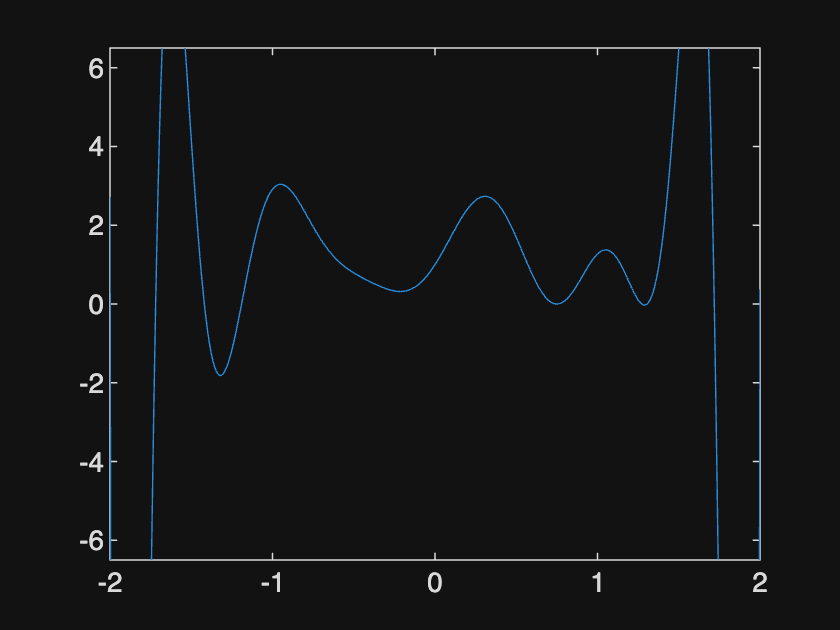

x=linspace(-2,2,15);
f=exp(sin(5.5*x));

u=linspace(-2,2,500);
v=newtondd(x,f,u);

plot(u,v);
ylim([-6.5,6.5])

function v=newtondd(x,f,u)

%first create divided difference table
    n=length(x);
    F=zeros(n,n);

    F(:,1)=f;

    for j=2:n
        for i=j:n
            F(i,j)=(F(i,j-1)-F(i-1,j-1)) / (x(i)-x(i-j+1));
        end
    end

    coeff=diag(F)';

    v=zeros(size(u));
    for k=1:length(u)
        pval=coeff(n);

        for i=n-1:-1:1
            pval=pval*(u(k)-x(i))+coeff(i);
        end
        v(k)=pval;
    end  
end